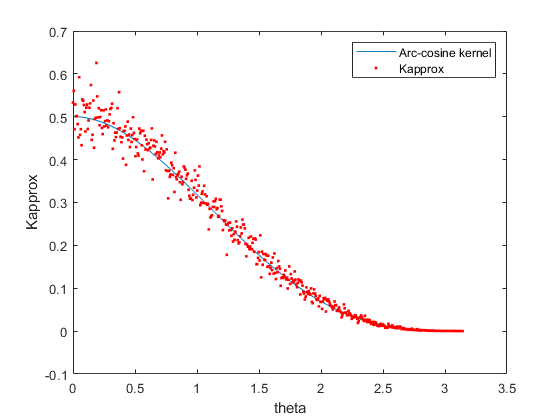

hw8 = csvread("hw8.csv");

X1 = hw8(:, 1:500);
X2 = hw8(:, 501:1000);
theta = hw8(:, 1001);

Kac = (1/(2*pi))*(sin(theta)+(pi-theta).*cos(theta));
plot(theta, Kac, '-');
hold on;

W = randn(500, 500);
KapproxVector = zeros(500, 1);
for i = 1:500
    x1 = X1(i, :)';
    x2 = X2(i, :)';
    sum = 0;
    for j = 1:500
        w = W(j, :);
        sum = sum + max(0, dot(w, x1)) * max(0, dot(w, x2));
    end
    Kapprox = sum / 500;
    KapproxVector(i, 1) = Kapprox;
end

scatter(theta, KapproxVector, '.', 'r');
hold off;

xlabel('theta');
ylabel('Kapprox');
legend('Arc-cosine kernel', 'Kapprox');